# Copyright(C) 2018 The University of Texas at Dallas

%  This work was supported by the Semiconductor Research Corporation (SRC) task 2712.029
%  through The University of Texas at Dallas' Texas Analog Center of Excellence (TxACE).

%  Redistributions and use of source must retain the above copyright notice
%  Redistributions in binary form must reproduce the above copyright notice

Modified By: Shengding Liu

Advisor: Prof. Jin Zhang

Department of Computer Science and Engineering

## Run this script at "Algorithms" Folder

## Modify all necessary directories and files

%--------------------------------------------------------------------------
% Path for the adcBinData
experiment_folderName = '.\Data';
adcBinData_subFolderName = 'valid';

% Path for the Calibration Data 
calData_fileName = '.\Algorithms\calibration\calData\calData_3Tx_4Rx.mat';
delayOffset_fileName = '.\Algorithms\calibration\calData\delayOffset_3Tx_4Rx.mat';

%Here we can add path for background calibration 

## Automated folder and file name generation

%--------------------------------------------------------------------------
addpath(genpath(pwd));

% Load sensorParams and sarParams
load(fullfile(experiment_folderName,adcBinData_subFolderName,'sensorParams'));
load(fullfile(experiment_folderName,adcBinData_subFolderName,'sarParams'));

% Load calData and delayOffsetx
load(fullfile(calData_fileName));
load(fullfile(delayOffset_fileName));

% Configure the ADC Bin Data Path
adcBinData_folderName = fullfile(experiment_folderName,adcBinData_subFolderName);


## Mean Target z-Distance

zTarget_mm = 250; % update the distance as needed.
sensorParams.Num_Frames = 400;
sarParams.Num_verticalScan = 50 %Update these two parameters as well

sarParams = 包含以下字段的 struct :
        Num_horizontalScan: 1
          Num_verticalScan: 50
    Horizontal_scanSize_mm: 400
      Vertical_scanSize_mm: 0
    Horizontal_stepSize_mm: 0
      Vertical_stepSize_mm: 7.5900
       Platform_Speed_mmps: 20
      Trigger_timeOffset_s: -1
           dataCaptureMode: 'Continuous'
        scanTrajectoryMode: 'Rectangular'


## Data Read Function call

%--------------------------------------------------------------------------
[rawData,sarParams,sensorParams] = dataReadFunction(sensorParams,sarParams,adcBinData_folderName);

     4     3   256     1   400    50



% rawData Format:
% (Num_RX * Num_TX) * Num_verticalScan * Num_horizontalScan * Samples_per_Chirp;
% sarParams and sensorParams may be updated because of data rearrangement process

## Just for a Validation

% Just For Test~
% rawData = read1843Data(".\mimo_test_1.bin", 256, 12);
rawData = read1843Data(".\test_auto_box_Raw_0.bin", 256, 4);
size(rawData)

ans =            4    15665664


% % 数据维度：原始数据是 [4, 309504]，总数据量为 4 * 309504
% numFrames = 403;
% numSamplesPerChirp = 256;
% numTX = 3;
% 
% 
% % 重塑数据为 [12, 403, 256, 3]
% rawDataReshaped = reshape(rawData, [12, sarParams.Num_verticalScan, numFrames, numSamplesPerChirp]);
% 
% % 如果你想把 TX 的维度放到第二维，数据将变成 [12, 1, 403, 256]
% 
% % 检查最终维度
% disp(size(rawDataReshaped));
% 
% rawData = rawDataReshaped;


## Remove Background Radiation (Optional) and Calibrate Data

%--------------------------------------------------------------------------
% 加载背景噪声数据
rawDataBackground = load('sar_background_noise.mat');

% 假设背景噪声数据在结构体中的字段名为 'rawData'
backgroundNoise = rawDataBackground.rawData;

% 进行差值计算
rawData = rawData - backgroundNoise;

## Calibrate rawData

%--------------------------------------------------------------------------
% rawData format should be: (Num_RX x Nu
% m_TX) x Num_verticalScan x Num_horizontalScan x Samples_per_Chirp;
rawDataCal = calibrateDataFunction(rawData,sensorParams,calData,delayOffset);

## Define Parameters

%--------------------------------------------------------------------------
frequency = [sensorParams.Start_Freq_GHz*1e9,sensorParams.Slope_MHzperus*1e12,sensorParams.Sampling_Rate_ksps*1e3,sensorParams.Adc_Start_Time_us*1e-6];
c = physconst('lightspeed');
Samples_per_Chirp = sensorParams.Samples_per_Chirp;
Num_TX = sensorParams.Num_TX;
Num_RX = length(sensorParams.RxToEnable);
Num_horizontalScan = sarParams.Num_horizontalScan;
Num_verticalScan = sarParams.Num_verticalScan;
yStepM_mm = sarParams.Vertical_stepSize_mm;
if (Num_horizontalScan~=1)
    if(sarParams.Horizontal_stepSize_mm == ...
            0)
        % for AMC4030 measurements
        xStepM_mm = sarParams.Platform_Speed_mmps * sensorParams.Frame_Repetition_Period_ms*1e-3;
        % for ESP32 based measurements
        % xStepM_mm = (sarParams.Horizontal_scanSize_mm)/(Num_horizontalScan-1);
    else
        xStepM_mm = sarParams.Horizontal_stepSize_mm;
    end
else
    xStepM_mm = 0;
end
lambda_mm = c/79e9*1e3; %  % center frequency

## Convert multistatic data to monostatic version

%--------------------------------------------------------------------------
% rawData format should be: (Num_RX * Num_TX) * Num_verticalScan * Num_horizontalScan * Samples_per_Chirp;
[~,rawDataMonostatic] = convertMultistaticToMonostatic(rawDataCal,frequency,xStepM_mm,yStepM_mm,zTarget_mm,'IWR1443',ones(1,Num_TX),ones(1,Num_RX));

k = k(:,:,1,1) =

   1.6207e+03


k(:,:,1,2) =

   1.6210e+03


k(:,:,1,3) =

   1.6213e+03


k(:,:,1,4) =

   1.6216e+03


k(:,:,1,5) =

   1.6218e+03


k(:,:,1,6) =

   1.6221e+03


k(:,:,1,7) =

   1.6224e+03


k(:,:,1,8) =

   1.6227e+03


k(:,:,1,9) =

   1.6230e+03


k(:,:,1,10) =

   1.6233e+03


k(:,:,1,11) =

   1.6236e+03


k(:,:,1,12) =

   1.6239e+03


k(:,:,1,13) =

   1.6242e+03


k(:,:,1,14) =

   1.6245e+03


k(:,:,1,15) =

   1.6248e+03


k(:,:,1,16) =

   1.6251e+03


k(:,:,1,17) =

   1.6254e+03


k(:,:,1,18) =

   1.6257e+03


k(:,:,1,19) =

   1.6260e+03


k(:,:,1,20) =

   1.6263e+03


k(:,:,1,21) =

   1.6266e+03


k(:,:,1,22) =

   1.6269e+03


k(:,:,1,23) =

   1.6271e+03


k(:,:,1,24) =

   1.6274e+03


k(:,:,1,25) =

   1.6277e+03


k(:,:,1,26) =

   1.6280e+03


k(:,:,1,27) =

   1.6283e+03


k(:,:,1,28) =

   1.6286e+03


k(:,:,1,29) =

   1.6289e+03


k(:,:,1,30) =

   1.6292e+03


k(:,:,1,31) =

   1.6295e+03


k(:,:,1,32) =

   1.6298e+03


k(:,:,1,33) =

## Make Uniform Virtual Array

%--------------------------------------------------------------------------
% rawData format should be: (Num_RX * Num_TX) * Num_verticalScan * Num_horizontalScan * Samples_per_Chirp;
rawDataUniform = reshape(rawDataMonostatic([1:4,9:12],:,:,:),[],Num_horizontalScan,Samples_per_Chirp);


%--------------------------------------------------------------------------
%-- Image Reconstruction Part
%--------------------------------------------------------------------------

## Reconstruct 3D or 2D Image

2D Slice

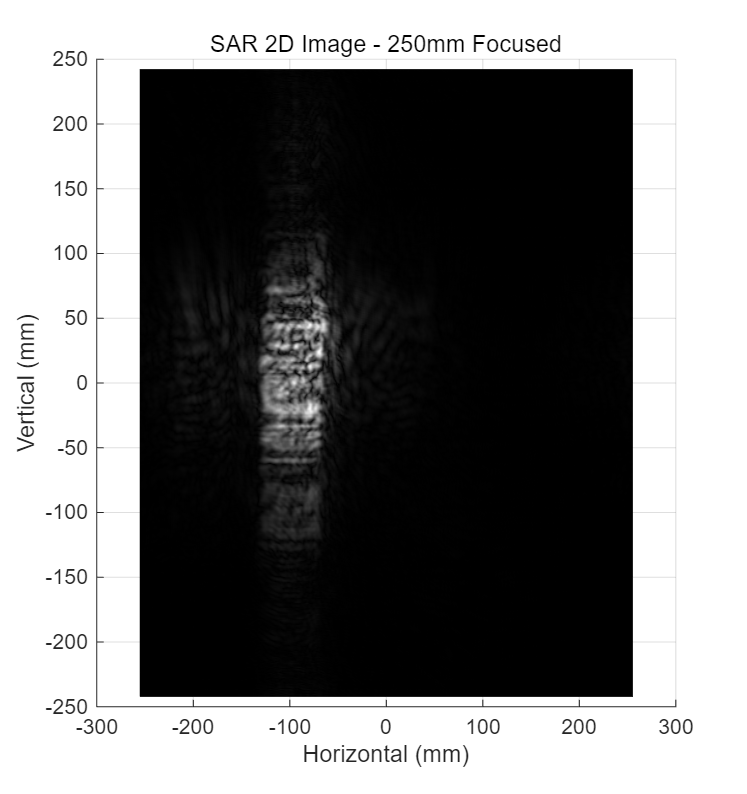

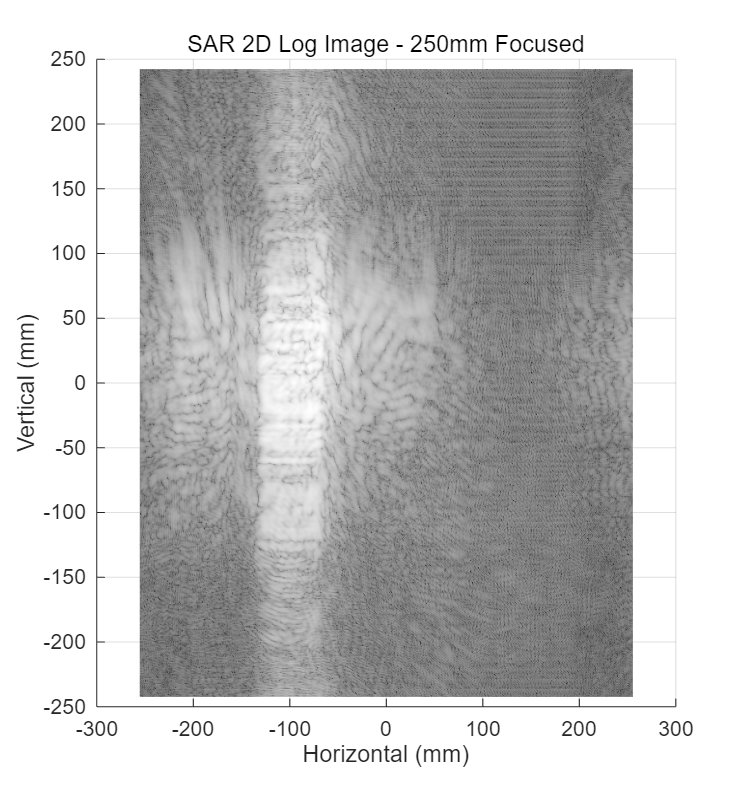

[sarImage2D,xRangeT2D,yRangeT2D,zRangeT2D] = reconstructSARimageFFT_3D(rawDataUniform,frequency,xStepM_mm,lambda_mm/4,-1,zTarget_mm,512);

% sarImage2D = reconstructSARimageFFT(rawDataUniform,frequency,xStepM_mm,lambda_mm/4,-1,zTarget_mm,512);

% 3D Image
[sarImage3D,xRangeT,yRangeT,zRangeT] = reconstructSARimageFFT_3D(rawDataUniform,frequency,xStepM_mm,lambda_mm/4,-1,-1,512);
% Filtering and visualizing
sarImage3DAbs = abs(sarImage3D);
volumeViewer(sarImage3DAbs);
% sarImage3DAbs = imgaussfilt3(sarImage3DAbs,0.5);
% volshow(sarImage3DAbs,'Renderer','MaximumIntensityProjection','Isovalue',0.9,'BackgroundColor',[0 0 0]);

## Isosurface patch plot

sarImage3DAbs_dB = mag2db(sarImage3DAbs/max(sarImage3DAbs(:)));
dynamicRange_dB = -15;
[X,Y,Z] = meshgrid(xRangeT,yRangeT,zRangeT);
[faces,vertices,colors] = isosurface(X,Y,Z,sarImage3DAbs_dB,dynamicRange_dB,Z);
figure('OuterPosition',[695 166 670 712]);
sarImage3DAbs_dB_patch = patch('Vertices',vertices(:,[3,1,2]),'Faces',faces(:,[3,1,2]),'FaceVertexCData',colors,...
    'FaceColor','interp','EdgeColor','interp');
grid on
xlabel('z-axis (mm)'); ylabel('x-axis (mm)'); zlabel('y-axis (mm)')
xlim([0 400]); ylim([-200 200]); zlim([-200 200]);
view(3)
colormap gray